Electricity Prices (retrieved 9/3/26 @ [Electricity Prices for Netherlands](https://thingler.io/country/Netherlands))

lambda = [12.27 11.2 10.98 11 11.3 11.1 14.09 22.25 24.58 16.49 13.07 10.09 7.62 6.99 7.24 9.13 10.05 12.71 22.34 24.79 21.78 17.06 15.54 13.98];
lambda = lambda / 1000; % cents / Wh
Ts = 900; % 15 minute samples
Nt = 60*60*24/Ts; % Number of samples in a day
Nh = 60*60/Ts; % Number of samples in an hour
lambda = kron(lambda, ones(1,Nt/24)); lambda = lambda./Nh; % divide cost into time steps - cents / W x (15mins)

## Defining system dynamics / matrices

kb = 1.645e-4; % between floors
kroof = 3.28e-5;
kfacade = 9.67e-5;
C_floor = 387210;

A = [-kb-kfacade kb 0 0;
     kb -kb-kb-kfacade kb 0;
     0 kb -kb-kb-kfacade kb;
     0 0 kb -kb-kfacade-kroof];

Bu_k = zeros(4,3,size(lambda,1)); % state selection, input selection, time step in day
B = zeros(4,4,size(lambda,1));

Bd = [kfacade;
      kfacade;
      kfacade;
      kfacade+kroof];

for i = 1:size(lambda,2)
    Bu = [1 0 0;
            0 1 0;
            0 0 1;
            0 0 1] * 1/(lambda(i) * C_floor);
    B(:,:,i) = [Bu, Bd];
    if rank(ctrb(A,B(:,:,i))) ~= 4 % check full rank for all B
        disp("NOT FULL RANK AT"+i)
    end
end


C = eye(4); D = zeros(4,4);
tf = ss(A,B,C,D);

% Used to determine sample time (previously)
[y,t] = step(tf(:,:,1));

stepinfo(y(:,1 ,1), t) % ~ 10 steps in rise time

ans = struct with fields:
         RiseTime: 1.6660e+04
    TransientTime: 3.1974e+04
     SettlingTime: 3.1974e+04
      SettlingMin: 4.1488
      SettlingMax: 4.6081
        Overshoot: 0
       Undershoot: 0
             Peak: 4.6081
         PeakTime: 7.8454e+04




tf_d = c2d(tf, Ts, 'zoh');
A = tf_d.A; B = tf_d.B; %B 
A = A(:,:,1); % expands to same size as B but all identical - reduce 
Bd = B(:,4,1); % Disturbance map, same situation as A
B = B(:,1:3,:); % true B (input map), time-varying

## Problem setup

% Parameters
x0 = [23; 1; 50; 18]; 
x_ref = 18; % Desired floor temperature 
Np = 2*Nt; % 2 days
n = size(B,1); 
n_dist = n+1; % state vector with disturbance
m = size(B,2);
N_b = size(B,3);

## Solving periodic riccati equation (find P and K)

% State vector for MPC is as follows:
    % State estimates (temperatures) n*Np
    % Disturbance estimate 1*Np
    % Inputs m
    % State error n
    % Input error m
    % Input reference m

% Standard vector [aka n_dist] (i.e. dynamic update, finding DARE solution):
    % States n
    % Disturbance 1

% Quadratic cost element (State error)
Qconst = 1;
Q_dist = Qconst * diag([ones(1,4) 0]); % 1 for each state, 0 for disturbance 

Q = Qconst * eye(4);

Rconst = 0.7;
R = Rconst * eye(m);

A_dist = [A Bd; zeros(1,4) 1];
B_dist = zeros(n_dist, m, N_b);
for k = 1:N_b
    B_dist(:,:,k) = [B(:,:,k); zeros(1,m)];
end

[P,K] = periodic_riccati(A_dist,B_dist,Q_dist,R);

## Observer design

controller_poles = zeros(n_dist,N_b);
for k = 1:N_b
    controller_poles(:,k) = eig(A_dist+B_dist(:,:,k)*K(:,:,k));
end
min_controller_pole = min(controller_poles(:)); % Fastest controller pole

A_C_aug = [eye(n)-A -Bd; C zeros(n,1)]; 
rank(A_C_aug); % Full rank - System is observable (see lecture 5 slide 16)

C_dist = [C zeros(n,1)];

% Fastest pole is 0.18 - make observer poles around 0.1
observer_poles = [0.09 0.095 0.1 0.105 0.11];
L = place(A_dist', C_dist',observer_poles).';
L_x = L(1:n, :); L_d = L(n+1:end,:);

## Stability stuff

% Defining inequality constraints
% Permittable temperature range
a_x1 = eye(n); b_x1 = 30*ones(n,1);
a_x2 = -1*eye(n); b_x2 = zeros(n,1);

% adding zero column to reflect added disturbance in state vector
a_x1 = [a_x1 zeros(n,1)]; a_x2 = [a_x2 zeros(n,1)];

% the state constraints are not currently varying in time it would be
% fairly easy to implement that into this bit if we decide that we want a
% varying temperature reference as the day progresses. 

a_x = zeros(8,n_dist,N_b); b_x = zeros(8,1,N_b);
for i = 1:N_b
    a_x(:,:,i) = [a_x1; a_x2]; 
    b_x(:,:,i) = [b_x1; b_x2] - a_x(:,:,i)*x_ref*ones(n_dist,1); % conversion to error coordinates
    % NB - doesn't matter above that the disturbance state is also getting
    % multiplied by x_ref since it is zeroed out in a_x
end

% No negative cost
a_u1 = -eye(m); b_u1 = zeros(m,1);
% Can't exceed 20c per floor in an hour (5c per 15 minutes)
a_u2 = eye(m); b_u2 = 5 * ones(m,1);

a_u = zeros(2*m,n_dist,N_b); b_u = zeros(2*m,1,N_b);

for i = 1:N_b
    a_u(:,:,i) = [a_u1; a_u2]*K(:,:,i); %HK
    b_u(:,:,i) = [b_u1; b_u2]-a_u(:,:,i)*x_ref*ones(n+1,1);
end


% add some more in plz

a = [a_x ; a_u]; b = [b_x ; b_u];
alpha = determine_worst_case_ellipsoid(a,b,P);
if isempty(nonzeros(alpha))
    disp("Alpha is all zeros");
else
    disp("Alpha is NOT all zeros");
end

Alpha is NOT all zeros


## Temporary - Defining parameters

k_current = 1; % t0 - time step (relative to cycle) at beginning of MPC
n_total_k = n_dist + m + n + m + m; % Dimension of state vector for one time step
n_total_Np = n_total_k*Np+n_dist; % Dimension of state vector for all time steps

Delta_u = 0.2; % Maximum difference between inputs (smooth operation - not currently used as it breaks everything)

params = struct( ...
    'A', A, ...
    'B', B, ...
    'A_dist', A_dist, ...
    'B_dist', B_dist, ...
    'Bd', Bd, ...
    'C', C, ...
    'D', D, ...
    'Q', Q, ...
    'R', R, ...
    'P', P, ...
    'x_ref', x_ref, ...
    'n', n, ...
    'm', m, ...
    'Np', Np, ...
    'n_dist', n_dist, ...
    'N_b', N_b, ...
    'n_total_k', n_total_k, ...
    'n_total_Np', n_total_Np, ...
    'Delta_u', Delta_u, ...
    'L',L, ...
    'L_x', L_x, ...
    'L_d', L_d);

## Running MPC

% Simulation duration
N_sim = 20; % length of simulation (x 15 minutes)
% Initial conditions
x_hat_0 = [0; 20; 15; 10; 24]; % Current state estimate (initial condition shown here)
% note : Setting disturbance estimate at 10 and then 200 shows how the effect is working, numbers are just off
x_0 = [10; 15; 20; 25];
d_0 = 10; % initial external temperature
y_0 = x_0;

% Defining state / input spaces
x = zeros(n,N_sim+1); 
x_hat = zeros(n_dist,N_sim+1);
u = zeros(m,N_sim);
d = zeros(1,N_sim+1); 

% Assigning initial conditions 
x(:,1) = x_0;
x_hat(:,1) = x_hat_0;
y_k = y_0;
d(1) = d_0;

for k = 1:N_sim % replace with another variable - works for now because it'll just run for 2 days

    k_current = mod(k-1,N_b)+1; % relative to period (find proper B, P)

    % Find optimal input at current estimate
    [x_hat_full, T1, T2, T3, T4, dhat, u1, u2, u3] = run_MPC(x_hat(:,k), y_k, k_current, params);

    % Packing here for clarity, change later
    u(:,k) = [u1(1); u2(1); u3(1)]; 
    x_hat(:,k+1) = [T1(1); T2(1); T3(1); T4(1); dhat];

    % Run real update with optimised input
    [x(:,k+1), d(k+1), y_k] = real_update(x(:,k), d(k), u(:,k), k_current, params);
end

Solved 776 variables, 781 equality, and 576 inequality constraints during the presolve.

 Iter            Fval  Primal Infeas    Dual Infeas  Complementarity  
    0    1.612844e+04   1.816436e+04   2.682056e-06     1.601671e+01  
    1    2.013659e+04   9.485878e+03   1.736992e-06     2.131399e+00  
    2    2.585505e+05   8.483138e+03   5.881982e-06     6.671991e+00  
    3    1.334770e+06   1.779990e+03   5.958611e-06     5.737167e+00  
    4    1.483813e+06   1.009477e+01   5.960556e-04     2.931050e-01  
    5    1.484921e+06   5.047387e-03   1.138211e-04     2.171987e-04  
    6    1.484921e+06   2.523750e-06   5.695017e-08     1.085994e-07  
    7    1.484921e+06   1.261744e-09   2.850697e-11     5.429968e-11  

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 


## Plotting data

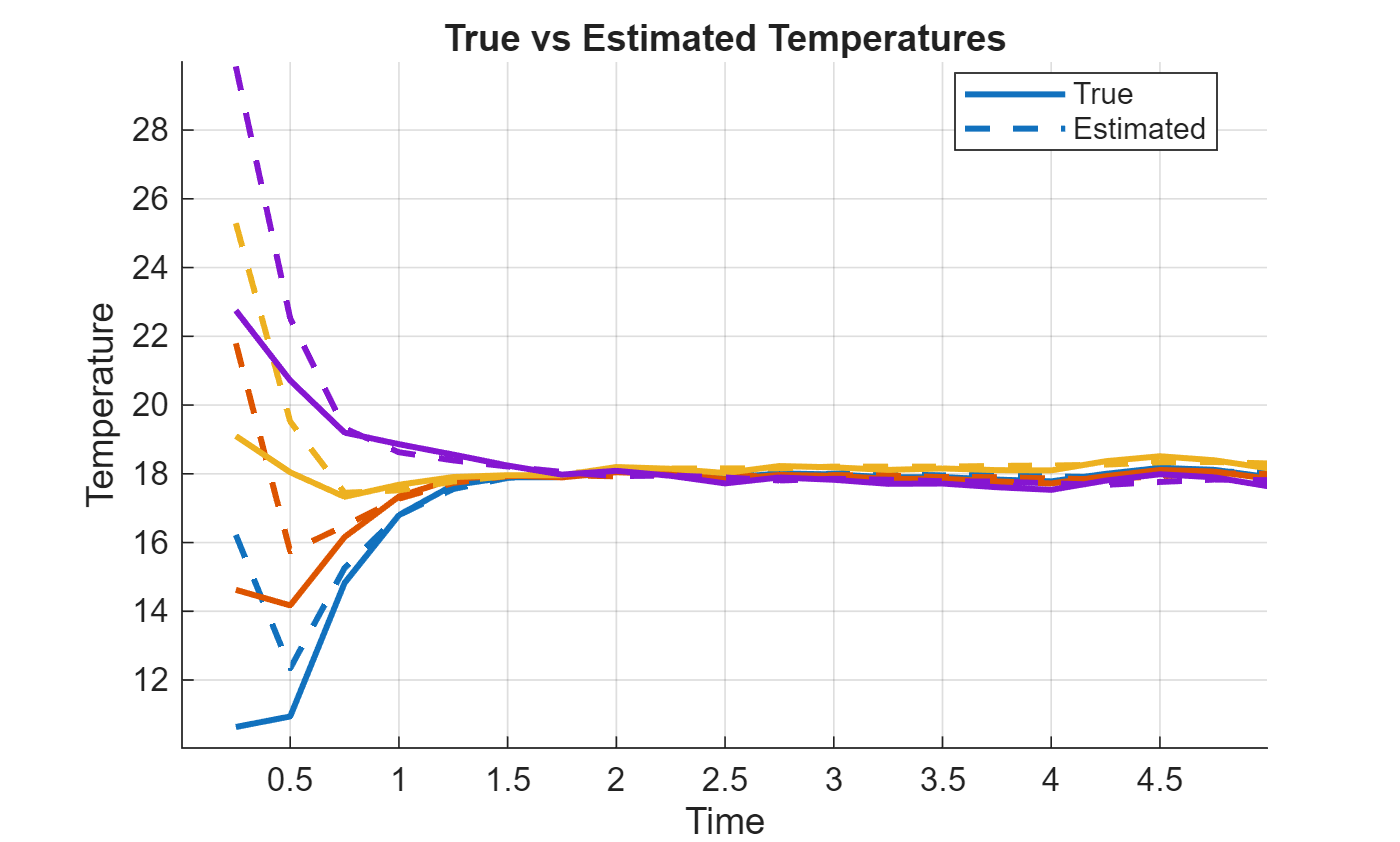

t = (1:N_sim)/Nh;

% State estimation
figure; hold on; grid on;

colors = lines(4); % consistent, visually distinct colours

for i = 1:4
    % True (solid)
    plot(t, x(i,2:end), ...
        'Color', colors(i,:), ...
        'LineWidth', 1.8);

    % Estimated (dashed)
    plot(t, x_hat(i,2:end), ...
        '--', ...
        'Color', colors(i,:), ...
        'LineWidth', 1.8);
end

% Minimal legend: style explains meaning
legend({'True', 'Estimated'}, 'Location', 'best');

xlabel('Time');
ylabel('Temperature');
title('True vs Estimated Temperatures');

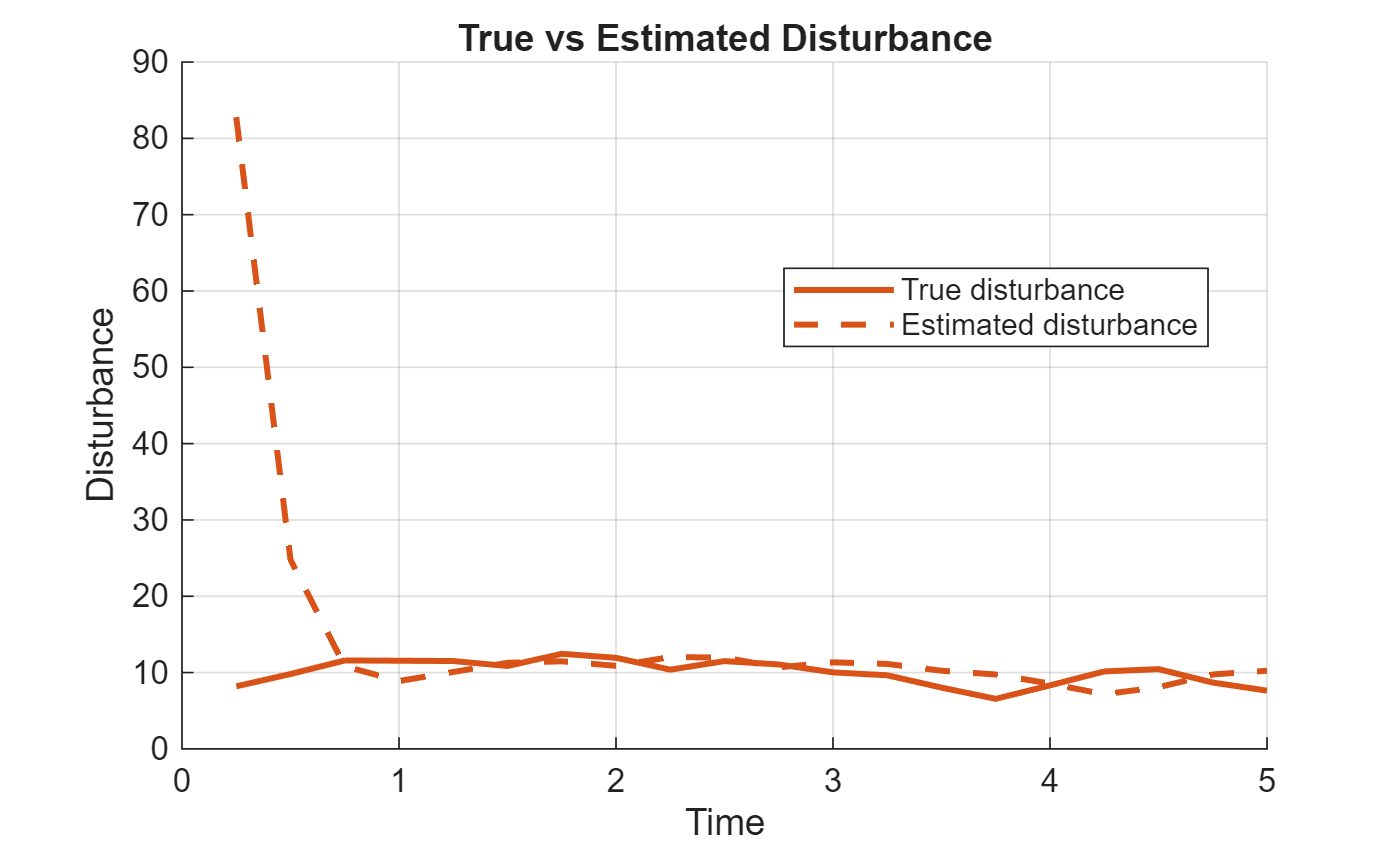


% Disturbance estimation
figure; hold on; grid on;

color = [0.8500 0.3250 0.0980]; % pick a distinct colour (MATLAB default orange)

% True disturbance (solid)
plot(t, d(2:end), ...
    'Color', color, ...
    'LineWidth', 1.8);

% Estimated disturbance (dashed)
plot(t, x_hat(5,2:end), ...
    '--', ...
    'Color', color, ...
    'LineWidth', 1.8);

legend({'True disturbance', 'Estimated disturbance'}, 'Location', 'best');

xlabel('Time');
ylabel('Disturbance');
title('True vs Estimated Disturbance');

### Plotting data (expected temperature evolution from final state)

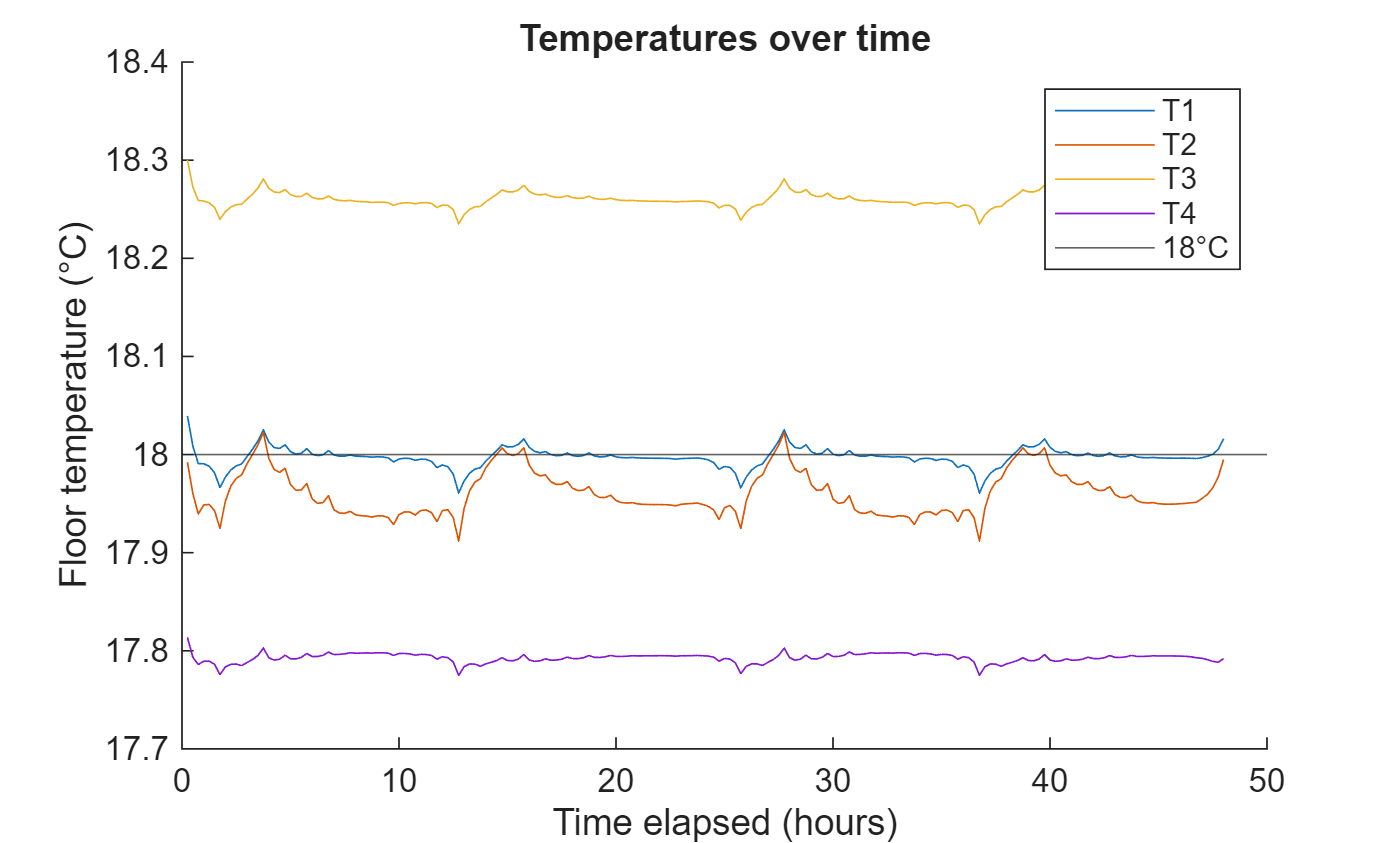

t = (1:Np)/Nh; % time
figure;
hold on
plot(t, T1);
plot(t,T2);
plot(t,T3);
plot(t,T4);
yline(x_ref);
title("Temperatures over time")
legend("T1", "T2", "T3", "T4", x_ref+"°C");
xlabel("Time elapsed (hours)"); ylabel("Floor temperature (°C)")

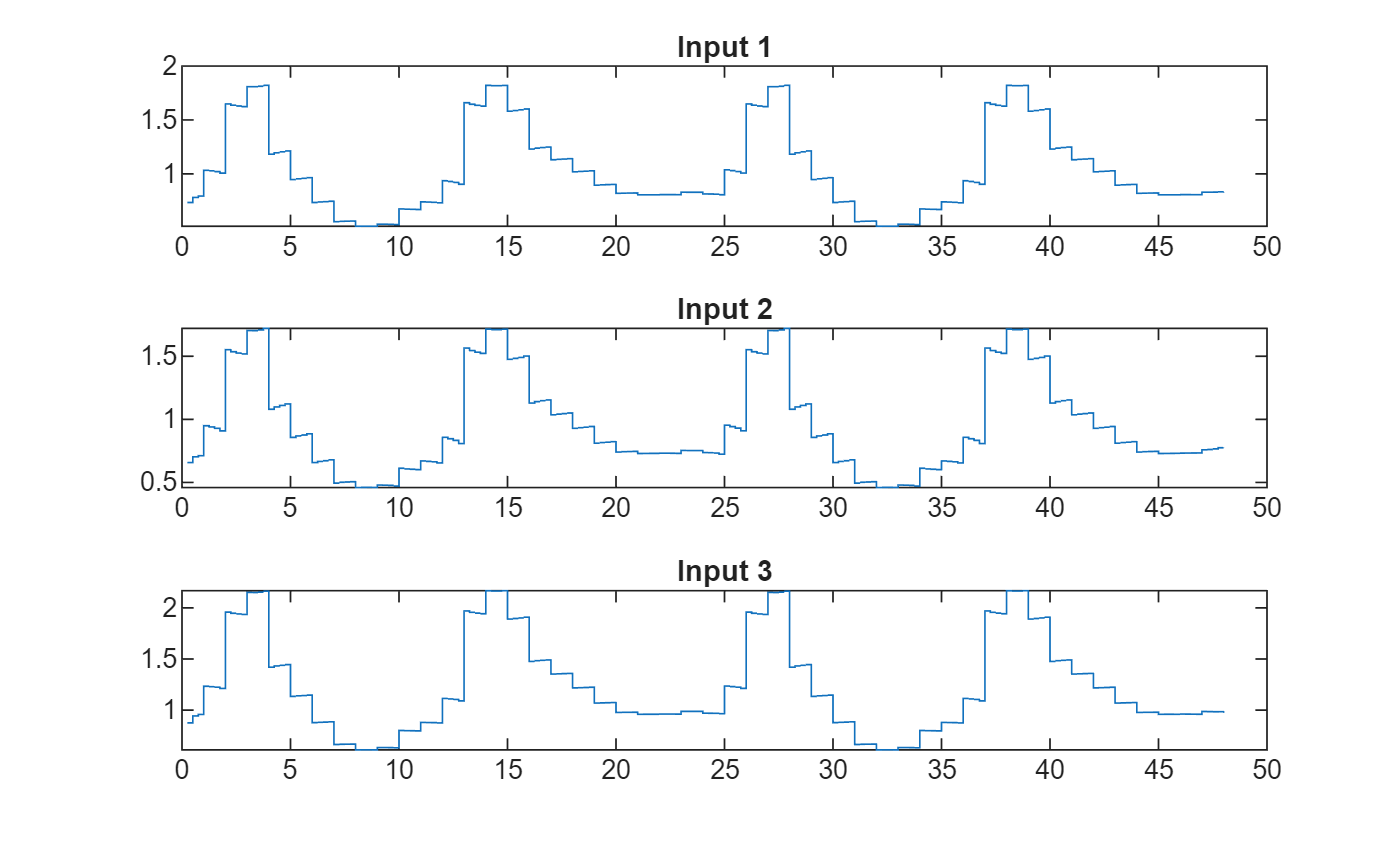


figure;
tiledlayout(3,1);
nexttile
stairs(t,u1);
title("Input 1");
nexttile
stairs(t,u2);
title("Input 2")
nexttile
stairs(t,u3);
title("Input 3")

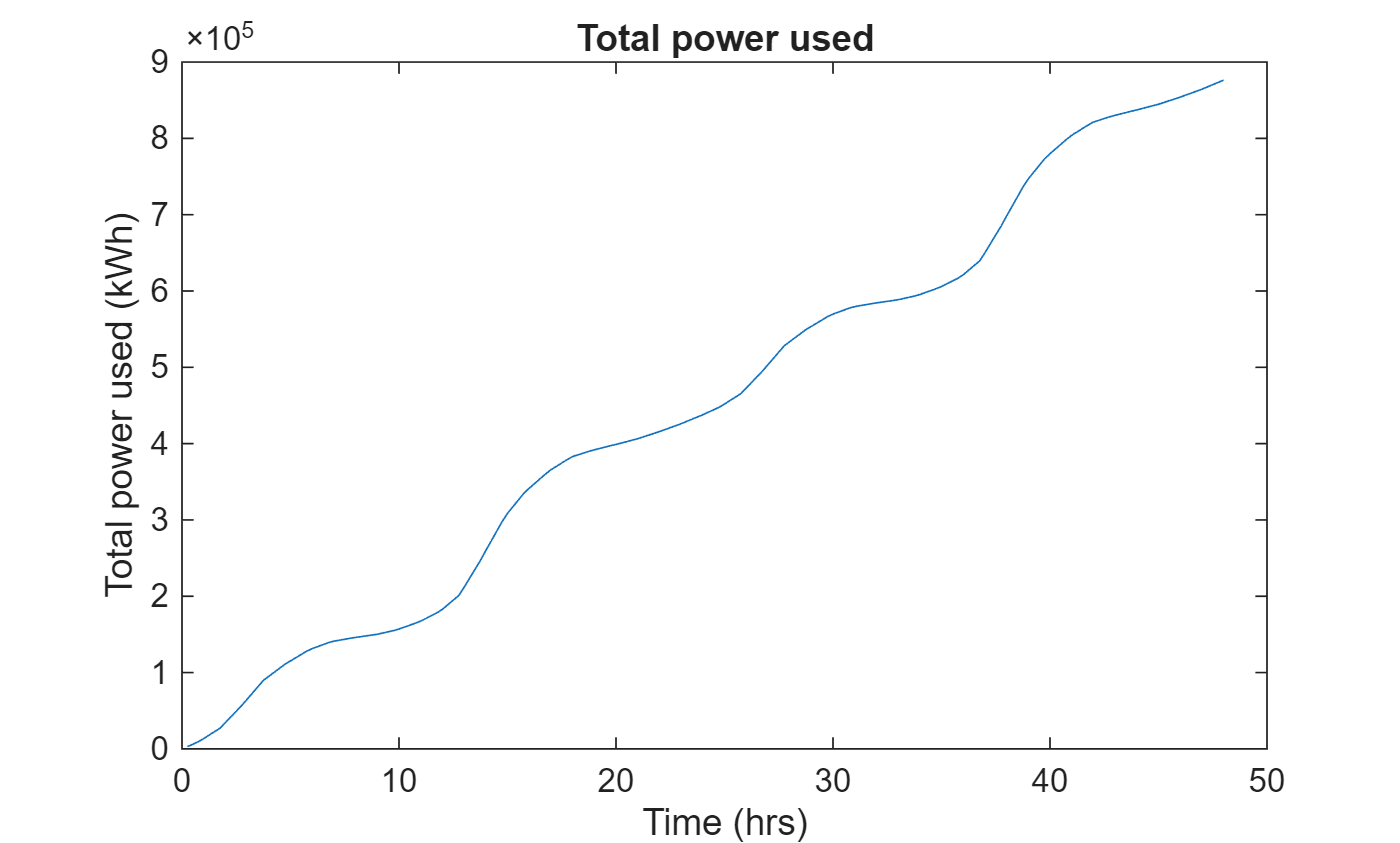


figure;
plot(t,4*cumsum((u1+u2+u3)./kron([1 1],lambda)')) % total kWh
title("Total power used")
xlabel("Time (hrs)"); ylabel("Total power used (kWh)");

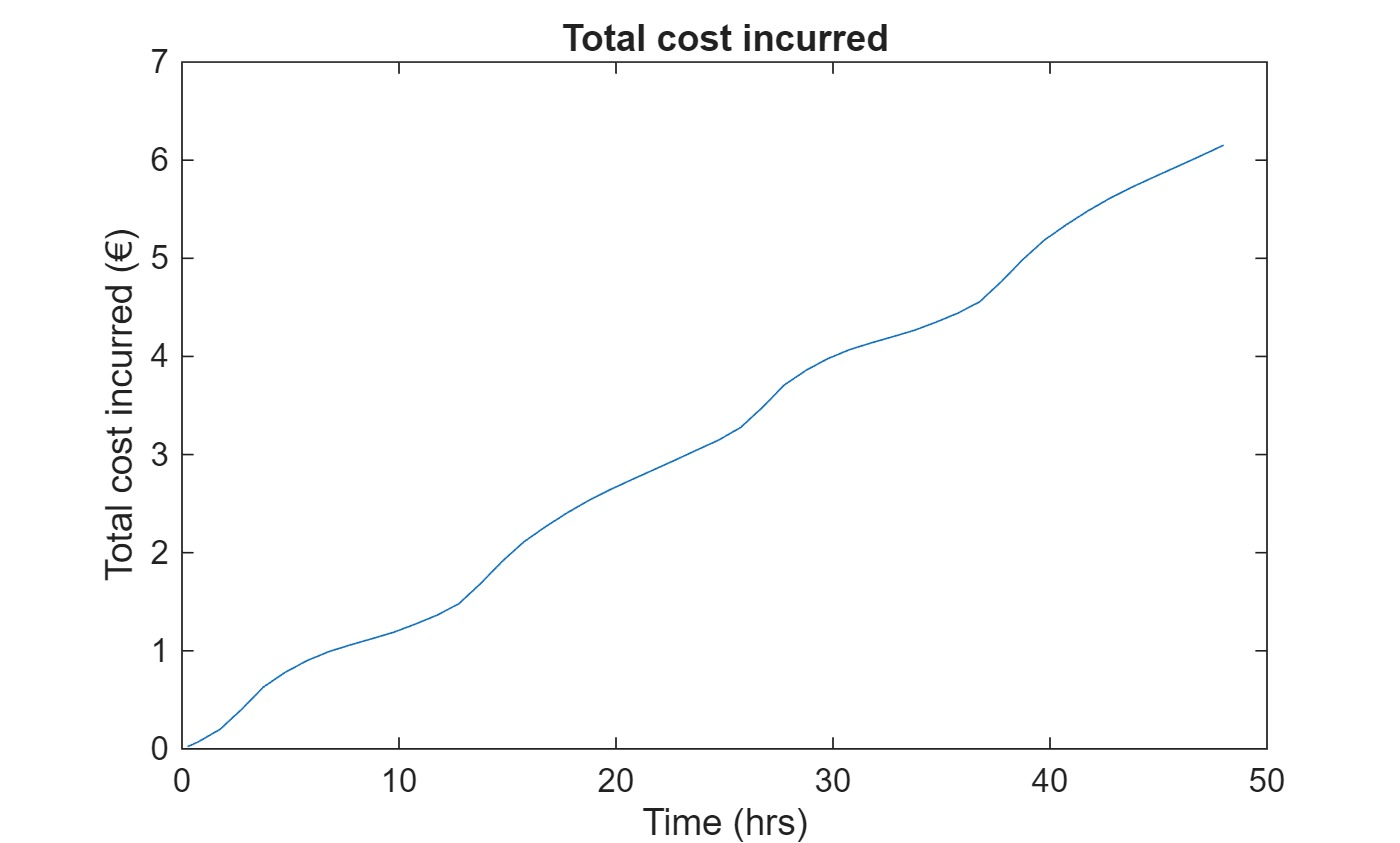


figure;
plot(t, cumsum(u1 + u2 + u3)/100);
title("Total cost incurred");
xlabel("Time (hrs)"); ylabel("Total cost incurred (€)");